# Supp Figure: SC Waves Persist following bilateral ablations

## Initialize Directory

defaultDir = 'M:\Bergles Lab Data\Papers\In Vivo Paper'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd('Supp - Bilateral ablations SC activity');


## Analyze wave frequency

files = loadFileList('.\Data\SCWaveAnalysis - Gribizis\*.mat');

eventNum = []


eventNum =

     []



for i=1:size(files,1)
        load(files{i});
        hits = region.durations(region.durations > 50);
        eventNum = [eventNum; size(hits,2)/10];
end


## Plot

compare2(eventNum([2:8]),eventNum(end-4:end),{'Control','Bilateral ablation'},'SC Waves Per Min',[3 2]);

    0.4380



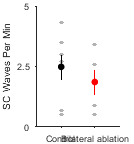

ylim([0 5])
yticks([0:2.5:5])
figQuality(gcf,gca,[1.4 1.50]);
set(gca,'LooseInset',get(gca,'TightInset')) ;
export_fig('.\EPS Panels\WT_VG3_eventsPerMinute.eps',gcf);